# Test

## Font Family

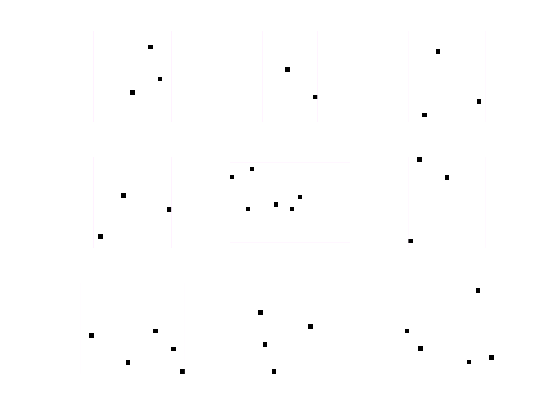

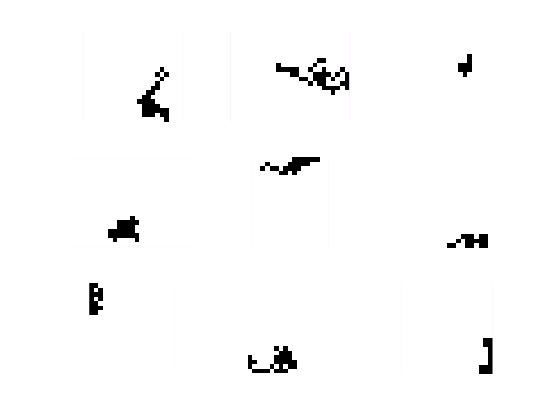

rows = 3;
cols = 3;
params = {
    {'random', @FontFamily.make_random_image, 0.01}
    {'random_walk', @FontFamily.make_random_walk_image, 0.1}
};

for i = 1:length(params)
    ff = FontFamily.make_font_family(params{i}{1}, params{i}{2}, params{i}{3});
    figure('Name', params{i}{1}, 'NumberTitle', 'off');
    for ii = 1:rows * cols
        subplot(rows, cols, ii);
        imshow(ff.chars{ii})
    end
end

## Text2Image

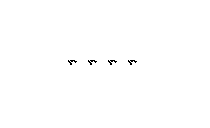

text = 'salam yasin halet chetore';
t2i = Text2Image(text);
t2i.font_scale = 5;
image = t2i.run();
figure('Name', text, 'NumberTitle', 'off');
imshow(image);